%页码：P134
%作者；暴富
%时间：2024-08-1
%项目：SVFB
%注意时间的设置与连续的不同

clc
clear
lineStyles = linspecer(6); % 指定线型颜色,一页有几条线

%%系统初始化
A = [0,1,0;0,0,1;-0.2,0.2,1.1];
B = [0;0;1];
C = [0,0,1];

G = diag([30,0,0,0,30]);
E = [0 1 1 1 0;...
     1 0 1 1 0;...
     1 1 0 0 1;...
     0 0 1 0 1;...
     0 1 0 1 0];
D = diag(sum(E,2));
L = D -E;
varGamma  = (eye(5)+D+G)\(L+G);

%特征值位置
eig_varGamma = eig(varGamma);
c0_SVFB = (max(real(eig_varGamma))+min(real(eig_varGamma)))/2;
r0_SVFB = max(abs(eig_varGamma - c0_SVFB));

%Riccati设计的稳定区域
Rc = ctrb(A,B);
rank(Rc); %ans = 3结果可控
Q = eye(3); %想要收敛快点就增大对角值
R = 1e-5;%希望控制输入的影响较小
[K,P] = dlqr(A,B,Q,R) ;
%定义矩阵M
M = inv(sqrtm(Q'))*A'*P*B*inv(B'*P*B)*B'*P*A*inv(sqrtm(Q));
r_SVFB = max(svd(M))^(-1/2);
c = 1/c0_SVFB;

%验证位似变换是否落在稳定区域

abs(c*eig_varGamma-1)<r_SVFB;
(r0_SVFB/c0_SVFB)<r_SVFB %等于1则满足条件

ans = logical
   1


# 注意仿真设计的时间与连续的不同

%%仿真初始化
N = 20;
t = 1:N;

%%agent初始化,6个agent，一个agent3个状态，每一页对应状态迭代
X = zeros(3,5,N);
X0 = zeros(3,1,N);
error = zeros(3,5,N);

%设置随机状态
X_initial = randn(3,5);
X(:,:,1) = X_initial;
X0_initial = randn(3,1);
X0(:,:,1) = X0_initial;

## **原始系统**

### **1.跟随者**


$$x_i\left(k+1\right)=Ax_i\left(k\right)+c\left(1+d_i+g_i\right)^{-1}BK \Bigg(\sum_{j\in N_i}e_{ij}(x_j-x_i)+g_i(x_0-x_i)\Bigg)$$


### 2.领导者：


$$$$
x_0(k+1)\,\,=\,\,Ax_0(k)
$$
$$


### 定义：


$$$
sum\_temp = \sum_{j\in N_i}e_{ij}(x_j-x_i)
$$$



$$$
sum\_leader = g_i(x_0-x_i)$$


### 整理的


$$x_i\left(k+1\right)=Ax_i\left(k\right)+c\left(1+d_i+g_i\right)^{-1}BK \Bigg(sum\_temp+sum\_leader\Bigg)$$



$$$$
x_0(k+1)\,\,=\,\,Ax_0(k)
$$
$$


for k = 2:N
    X0(:,1,k) = A*X0(:,1,k-1);
    for i = 1:5
        sum_temp = 0;
        sum_leader = G(i,i)*(X0(:,1,k-1)-X(:,i,k-1));
        for j = 1:5
            sum_temp = sum_temp + E(i,j)*(X(:,j,k-1)-X(:,i,k-1));
        end
        X(:,i,k) = A*X(:,i,k-1) + c*(1+D(i,i)+G(i,i))^(-1)*B*K*(sum_temp+sum_leader);
    end
    error(:,:,k-1) = X(:,:,k-1) - X0(:,:,k-1);
end

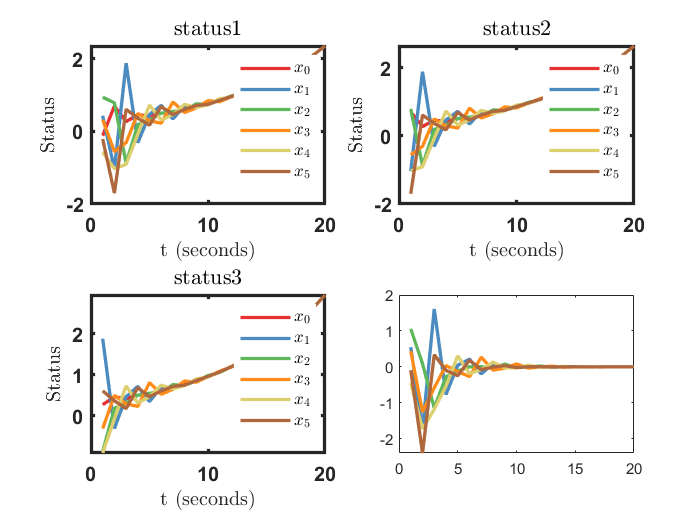

%%绘图
%% 绘制结果
hf = figure;  %新建 图形控制句柄
hf.Color= [1 1 1]; % 控制图形的整体颜色。（scope中被默认为灰黑色，此处修改为白色）

subplot(2,2,1)
plot(t,reshape(X0(1,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(1,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(1,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(1,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(1,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(1,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','status1')

subplot(2,2,2)
plot(t,reshape(X0(2,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(2,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(2,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(2,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(2,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','status2')

subplot(2,2,3)
plot(t,reshape(X0(3,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(3,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','status3')

subplot(2,2,4)
%领导者状态1与跟随者状态1的误差
plot(t,reshape(error(1,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2);
hold on
plot(t,reshape(error(1,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(error(1,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(error(1,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(error(1,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 

%FigPorperty('t (seconds)','Status','error_status1')